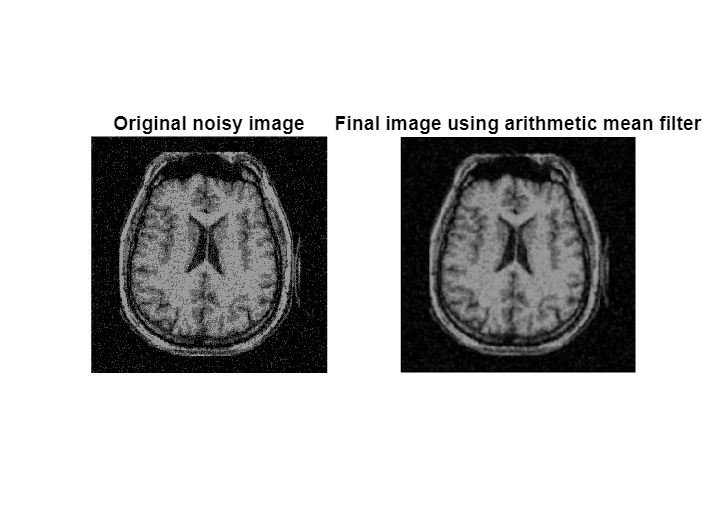

clc;clear;close all;

i=uigetfile('*.*');
I=imread(i);
J=rgb2gray(I);
subplot(1,2,1);
imshow(I);title("Original noisy image");
K=padarray(J,[1,1],0);
K=double(K);
[rows,columns]=size(K);
L=zeros(rows,columns);
for r=2:rows-1
    for c=2:columns-1
        filt=[K(r,c),K(r-1,c),K(r+1,c),K(r,c-1),K(r,c+1),K(r-1,c-1),K(r-1,c+1),K(r+1,c-1),K(r+1,c+1)];
        x=mean(filt);
        L(r,c)=x;
    end
end
subplot(1,2,2);
M=uint8(L);
imshow(M );title("Final image using arithmetic mean filter");

